# Repeat Reunion Part 4B Within Variance 2, Interaction Vector Distances

## Interaction number vectors (each interaction vector has equal number of interactions)

### Create intvecs with 1 through 30 interactions

Calculate number of interactions per session.

Used to determine an appropriate number of interactions for our interaction vectors

betypes = [-1 1 2 3 5];
colorcodes_f = [.75 0 0 ; .4 0 0 ; 1 .35 .35];
colorcodes_m = [0 0 .75 ; 0 0 .4 ; .35 .35 1];

%% The following was temporarily used to assess number of interactions per sessions

% numbehaves = nan(length(fem_pairs), 5);
% for i = 1:length(fem_pairs)
%     for j = 1:5
%        curind = find(rdb_rr.paircode == i & rdb_rr.exposurenum' == j);
%        numbehaves(i,j) = length(find(ismember(fix(rdb_rr.be_identcode(:,curind)), betypes)));      
%     end    
% end
% 
% length(find(numbehaves >= 16))/length(find(numbehaves))
% 
% hist(numbehaves(find(numbehaves)), 100)


Create a cell array of event-based interaction vectors across different 

IntVecs = cell(30,1);
for i = 1:30
  IntVecs{i} = Rdb_intvecs(rdb_rr, i);
end

4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400440480520560600640
 done 
4080120160200240280320360400

### Compute within-session and between-dyad distances using interaction number vectors

(Takes about 45 s if running up to 27)

warning('off', 'all');

%Distset = cell(length(fem_pairs), 5);
meandists_fe = nan(length(fem_pairs), 5, length(IntVecs));
meaninterdists_fe = nan(length(fem_pairs), 5, length(IntVecs));
numIV_f = nan(length(fem_pairs), 5, length(IntVecs));

meandists_fc = nan(length(fem_pairs), 5, length(IntVecs));
meaninterdists_fc = nan(length(fem_pairs), 5, length(IntVecs));
numIV_fc = nan(length(fem_pairs), 5, length(IntVecs));


for k = 1:length(IntVecs)
for i = 1:length(fem_pairs)
    for j = 1:5
        curind = find(rdb_rr.paircode == fem_pairs(i) & rdb_rr.exposurenum' == j);
        if ismember(fem_pairs(i), fem_pairs(ostrangers_f))
            otherind = find(ismember(rdb_rr.paircode, fem_pairs(ostrangers_f)) & rdb_rr.exposurenum' == j);
        elseif ismember(fem_pairs(i), fem_pairs(cagemates_f))
            otherind = find(ismember(rdb_rr.paircode, fem_pairs(cagemates_f)) & rdb_rr.exposurenum' == j);
        elseif ismember(fem_pairs(i), fem_pairs(nstrangers_f))
            otherind = find(ismember(rdb_rr.paircode, fem_pairs(nstrangers_f)) & rdb_rr.exposurenum' == j);
        end
        if ~isempty(curind)
            if size(IntVecs{k}{curind},2) > 1
                numIV_f(i,j,k) = 1;

                curIVs = IntVecs{k}{curind}';
                othIVs = [IntVecs{k}{otherind}]';
                
                Distset = squareform(pdist(curIVs, 'euclidean'));
                Distset(find(eye(length(Distset)))) = nan;
                
                Interdistset = squareform(pdist(othIVs, 'euclidean'));
                
                meandists_fe(i,j,k) = nanmean(reshape(Distset, 1, []));
                meaninterdists_fe(i,j,k) = nanmean(reshape(Interdistset(1:size(curIVs,1), size(curIVs,1)+1:size(Interdistset,2)), 1, []));

                Distset = squareform(pdist(curIVs, 'cosine'));
                Distset(find(eye(length(Distset)))) = nan;
                
                Interdistset = squareform(pdist(othIVs, 'cosine'));
                
                meandists_fc(i,j,k) = nanmean(reshape(Distset, 1, []));
                meaninterdists_fc(i,j,k) = nanmean(reshape(Interdistset(1:size(curIVs,1), size(curIVs,1)+1:size(Interdistset,2)), 1, []));
                               
            else 
                numIV_f(i,j,k) = 0;
            end
        end
    end
end
end


meandists_me = nan(length(fem_pairs), 5, length(IntVecs));
meaninterdists_me = nan(length(fem_pairs), 5, length(IntVecs));
meandists_mc = nan(length(fem_pairs), 5, length(IntVecs));
meaninterdists_mc = nan(length(fem_pairs), 5, length(IntVecs));

numIV_m = nan(length(mal_pairs), 5, length(IntVecs));
for k = 1:length(IntVecs)
for i = 1:length(mal_pairs)
    for j = 1:5
        curind = find(rdb_rr.paircode == mal_pairs(i) & rdb_rr.exposurenum' == j);
        if ismember(mal_pairs(i), mal_pairs(ostrangers_m))
            otherind = find(ismember(rdb_rr.paircode, mal_pairs(ostrangers_m)) & rdb_rr.exposurenum' == j);
        elseif ismember(mal_pairs(i), mal_pairs(cagemates_m))
            otherind = find(ismember(rdb_rr.paircode, mal_pairs(cagemates_m)) & rdb_rr.exposurenum' == j);
        elseif ismember(mal_pairs(i), mal_pairs(nstrangers_m))
            otherind = find(ismember(rdb_rr.paircode, mal_pairs(nstrangers_m)) & rdb_rr.exposurenum' == j);
        end
        if ~isempty(curind)
            if size(IntVecs{k}{curind(1)},2) > 1
                numIV_m(i,j,k) = 1;

                curIVs = IntVecs{k}{curind(1)}';
                othIVs = [IntVecs{k}{otherind}]';
                
                Distset = squareform(pdist(curIVs, 'euclidean'));
                Distset(find(eye(length(Distset)))) = nan;
                
                Interdistset = squareform(pdist(othIVs, 'euclidean'));
                
                meandists_me(i,j,k) = nanmean(reshape(Distset, 1, []));
                meaninterdists_me(i,j,k) = nanmean(reshape(Interdistset(1:size(curIVs,1), size(curIVs,1)+1:size(Interdistset,2)), 1, []));

                Distset = squareform(pdist(curIVs, 'cosine'));
                Distset(find(eye(length(Distset)))) = nan;
                
               
                Interdistset = squareform(pdist(othIVs, 'cosine'));

                meandists_mc(i,j,k) = nanmean(reshape(Distset, 1, []));
                meaninterdists_mc(i,j,k) = nanmean(reshape(Interdistset(1:size(curIVs,1), size(curIVs,1)+1:size(Interdistset,2)), 1, []));
                                

            else 
                numIV_m(i,j,k) = 0;
            end
        end
    end
end
end

%sanity check: are distances correlated with length?

tempint = IntVecs{15};
for i = 1:length(tempint) % use 15 for now, since this gives us solid results below
    numblocks(i) = size(tempint{i},2);

                Distset = squareform(pdist(tempint{i}, 'cosine'));
                Distset(find(eye(length(Distset)))) = nan;
               % sanitydist(i) = nanmean(reshape(Distset, 1, []));
                sanitydist(i) = nanmean(diag(Distset,1));
end

tempnotiszero = find(sanitydist ~= 0 & ~isnan(sanitydist));
[a b] = corr(numblocks(tempnotiszero)', sanitydist(tempnotiszero)');

%again for scrambled

for i = 1:length(tempint) % use 15 for now, since this gives us solid results below
    numblocks(i) = size(tempint{i},2);
    stt = tempint{i};
    if ~isempty(stt)
        for j = 1:size(stt,2)
            stt(:,j) = stt(randperm(size(stt,1)),j);
        end
    end
        Distset = squareform(pdist(stt, 'cosine'));
        Distset(find(eye(length(Distset)))) = nan;
%        scram_sanitydist(i) = nanmean(reshape(Distset, 1, []));
        scram_sanitydist(i) = nanmean(diag(Distset,1));
end
tempnotisnan = find(~isnan(sanitydist));
tempnotiszero = find(sanitydist ~= 0 & ~isnan(sanitydist));
figure
hold

Current plot held


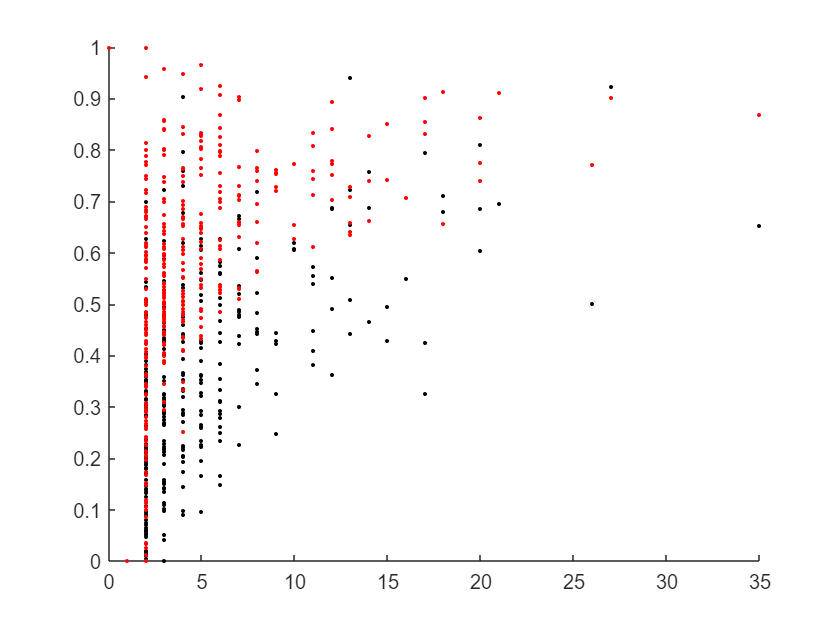

plot(numblocks(tempnotisnan), sanitydist(tempnotisnan), 'k.');
plot(numblocks(tempnotisnan), scram_sanitydist(tempnotisnan), 'r.')
box off

[a b] = corr(numblocks(tempnotiszero)', sanitydist(tempnotiszero)')

a = -0.2176

b = 1.6516e-06

[a b] = corr(numblocks(tempnotiszero)', scram_sanitydist(tempnotiszero)')

a = -0.0929

b = 0.0427

### Plot within vs. betwen distances and number of valid sessions

num_m_f = nan(1,30);
for i = 1:30
    num_m_f(i) = nansum(reshape(numIV_f(:,:,i), 1, []))/length(find(~isnan(numIV_f(:,:,i)))); 
end

mdid_fe = meandists_fe./meaninterdists_fe;
mdid_fc = meandists_fc./meaninterdists_fc;

mdid_m_fe = nan(1,30);
mdid_m_fc = nan(1,30);
for i = 1:30
    mdid_m_fe(i) = nanmean(nanmean(mdid_fe(:,:,i))); 
end
for i = 1:30
    mdid_m_fc(i) = nanmean(nanmean(mdid_fc(:,:,i))); 
end

figure
subplot(1,2,1)
[AX, H1, H2] = plotyy(1:30,num_m_f,1:30,mdid_m_fc);
hold(AX(2))

Current plot held


plot(AX(2), 1:30, mdid_m_fe)

num_m_m = nan(1,30);
for i = 1:30
    num_m_m(i) = nansum(reshape(numIV_m(:,:,i), 1, []))/length(find(~isnan(numIV_m(:,:,i)))); 
end

mdid_me = meandists_me./meaninterdists_me;
mdid_mc = meandists_mc./meaninterdists_mc;

mdid_m_me = nan(1,30);
mdid_m_mc = nan(1,30);
for i = 1:30
    mdid_m_me(i) = nanmean(nanmean(mdid_me(:,:,i))); 
end
for i = 1:30
    mdid_m_mc(i) = nanmean(nanmean(mdid_mc(:,:,i))); 
end

subplot(1,2,2)
[AX, H1, H2] = plotyy(1:30,num_m_m,1:30,mdid_m_mc);
hold(AX(2))

Current plot held


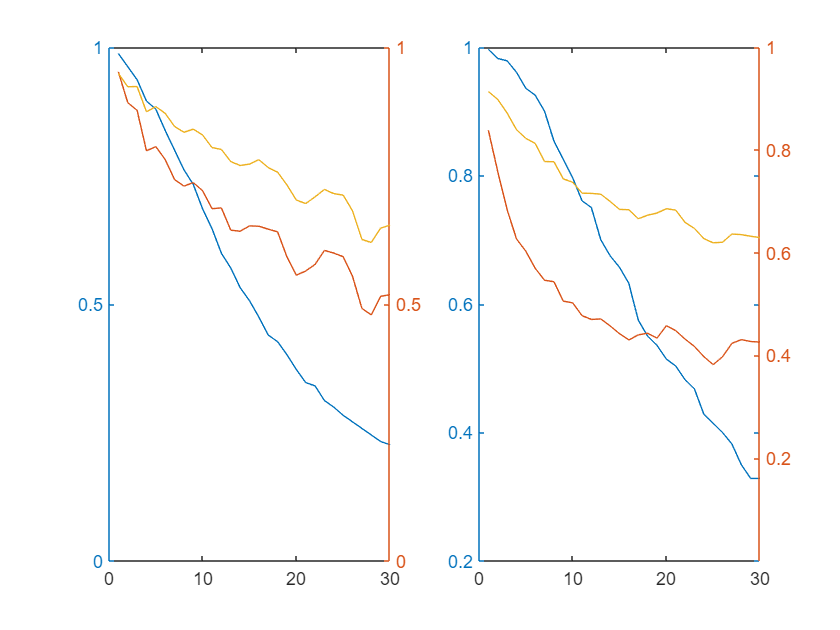

plot(AX(2), 1:30, mdid_m_me)
set(AX(2), 'YLim', [0 1])

### Compare cagemate and stranger for days 1 and 5, across all interaction vector numbers

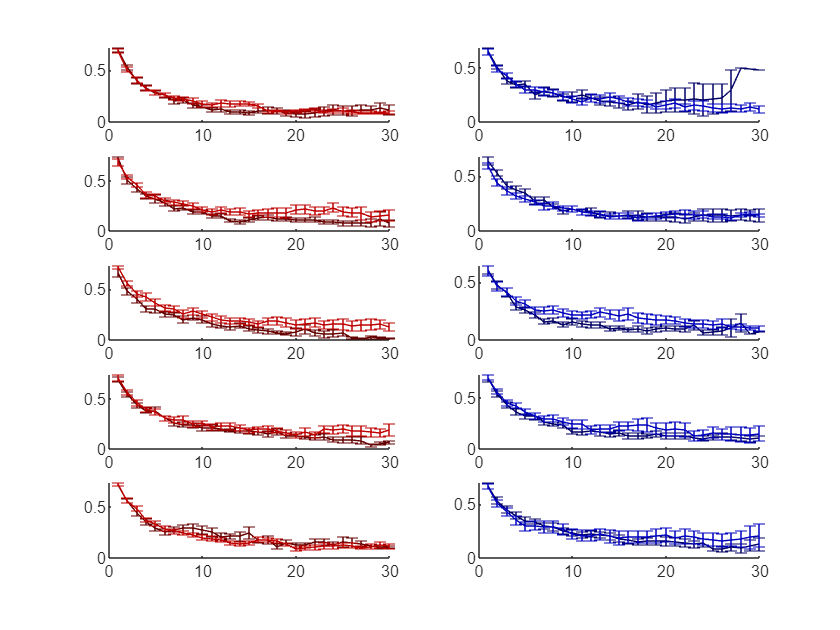

figure
for n = 1:2
 if n == 1
     meandists = meandists_fc;
     numIV = numIV_f;
     cagemates = cagemates_f;
     ostrangers = ostrangers_f;
     nstrangers = nstrangers_f;
     colorcodes = colorcodes_f;
 elseif n == 2
     numIV = numIV_m;
     meandists = meandists_mc;
     cagemates = cagemates_m;
     ostrangers = ostrangers_m;
     nstrangers = nstrangers_m;
     colorcodes = colorcodes_m;
 end


for i = 1:5
    cag_mdI{i,n} = squeeze(meandists(cagemates, i, :));%./repmat(1:30, length(cagemates_f), 1);
    str_mdI{i,n} = squeeze(meandists(ostrangers, i, :));%./repmat(1:30, length(cagemates_f), 1);

    nst_mdI{i,n} = squeeze(meandists(nstrangers, i, :));%./repmat(1:30, length(nstrangers_f), 1);

    numIVcag{i,n} = nansum(squeeze(numIV(cagemates, i, :)));  
    numIVstr{i,n} = nansum(squeeze(numIV(ostrangers, i, :)));
    numIVnst{i,n} = nansum(squeeze(numIV(nstrangers, i, :)));
end


for i = 1:5
    subplot(5,2,i*2-1 +n-1)
    hold on
    e1 = errorbar(1:30, nanmean(cag_mdI{i,n}), nanstd(cag_mdI{i,n})./sqrt(numIVcag{i,n}), 'Color', colorcodes(2,:));
    e2 = errorbar(1:30, nanmean(str_mdI{i,n}), nanstd(str_mdI{i,n})./sqrt(numIVstr{i,n}), 'Color', colorcodes(1,:));
%    e3 = errorbar(1:30, nanmean(nst_mdI{i,n}), nanstd(nst_mdI{i,n})./sqrt(numIVnst{i,n}), 'Color', colorcodes(3,:));
end

end

%e3 = errorbar(1:30, nanmean(str_mdI_5), nanstd(str_mdI_5)./sqrt(numIVstr_5), 'r');

### Statistical comparison for day 1 -5, across all 1 through 30 interaction numbers

%Need a nonlinear regression model that takes into account 3 factors:
% 1) Block number (exponential, with beta < 1)
% 2) cagemate/stranger (categorical)
% 3) day (can be linear (or category?)

n = 2;
sn = size(str_mdI{1,n},1);

blocknumbermat = repmat(1:30, sn*5*2, 1);
blocknumber_vec = reshape(blocknumbermat, [], 1);

cagstrmat = repmat([zeros(sn,30) ; ones(sn,30)], 5, 1);
cagstr_vec = reshape(cagstrmat, [],1);

daymat = []; 
for i = 1:5
    daymat = [daymat ; repmat(i,sn,30)]; 
end
day_vec = reshape([daymat daymat], [], 1);


regmat = [cat(1,cag_mdI{:,n}) ; cat(1,str_mdI{:,n})]; %concatenating all days in males, cagemate and stranger
reg_vec = reshape(regmat, [], 1);

%X = [ones(length(reg_vec),1) cagstr_vec blocknumber_vec day_vec];

X = [ones(length(reg_vec),1) cagstr_vec blocknumber_vec day_vec day_vec.*cagstr_vec];% blocknumber_vec.*cagstr_vec.*day_vec];

% create a model to use for regression
% here the first column will be ones (the intercept)
%        second will be cagemate/stranger
%        third will be blocknumber (exponential)
%        forth will be day number

%modelfun = @(b,x)(b(1).*x(:,1)+b(2).*x(:,2).*(x(:,3).^b(2)).*b(3).*x(:,4));
%beta = nlinfit([ones(length(reg_vec),1) cagstr_vec blocknumber_vec day_vec], reg_vec, modelfun, [.25 0 0 0]);

indnotnan = find(~isnan(reg_vec) & reg_vec ~= 0);
reg_vec = reg_vec(indnotnan);
X = X(indnotnan,:);


[B,BINT,R,RINT,STATS] = regress(log(reg_vec), X);

BINT

BINT =    -1.1626   -0.8799
   -0.0526    0.3096
   -0.0674   -0.0581
   -0.0359    0.0409
   -0.0445    0.0624


%AREA UNDER THE CURVE _WILL NOT WORK_ DUE TO MISSING DATA (BIASES FOR
%SESSIONS WITH FEWER INTERACTIONS)
% auc_cag = nan(26,5,2);
% auc_str = nan(26,5,2);
% 
% for n = 1:2
%     if n == 1
%         nlen = 26;
%     else
%         nlen = 22;
%     end
%     for i = 1:5
%         auc_cag(1:nlen,i,n) = nanmean(cag_mdI{i,n}, 2)*30;
%         auc_str(1:nlen,i,n) = nanmean(str_mdI{i,n}, 2)*30;
%     end
% end
% 
% auc_cag(auc_cag == 0) = nan;
% auc_str(auc_str == 0) = nan;
% 
% figure
% hold
% for n = 1:2
%     if n == 1
%         colorcodes = colorcodes_f;
%     else
%         colorcodes = colorcodes_m;
%     end
% %    e{1,n} = errorbar(1:5, nanmean(auc_cag(:,:,n)), nanstd(auc_cag(:,:,n))/sqrt(length(find(~isnan(auc_cag(:,1,n))))), 'Color', colorcodes(2,:));
% %    e{2,n} = errorbar(1:5, nanmean(auc_str(:,:,n)), nanstd(auc_str(:,:,n))/sqrt(length(find(~isnan(auc_str(:,1,n))))), 'Color', colorcodes(1,:));
% 
%     e{1,n} = errorbar(1:5, nanmean(auc_str(:,:,n)-auc_cag(:,:,n)), nanstd(auc_str(:,:,n)-auc_cag(:,:,n))/sqrt(length(find(~isnan(auc_cag(:,1,n))))), 'Color', colorcodes(1,:));
%     
% 
% 
% end
% set(get(e{1,n}, 'Parent'), 'XLim', [0.75 5.25])

blocknum = 15;

figure
hold

Current plot held


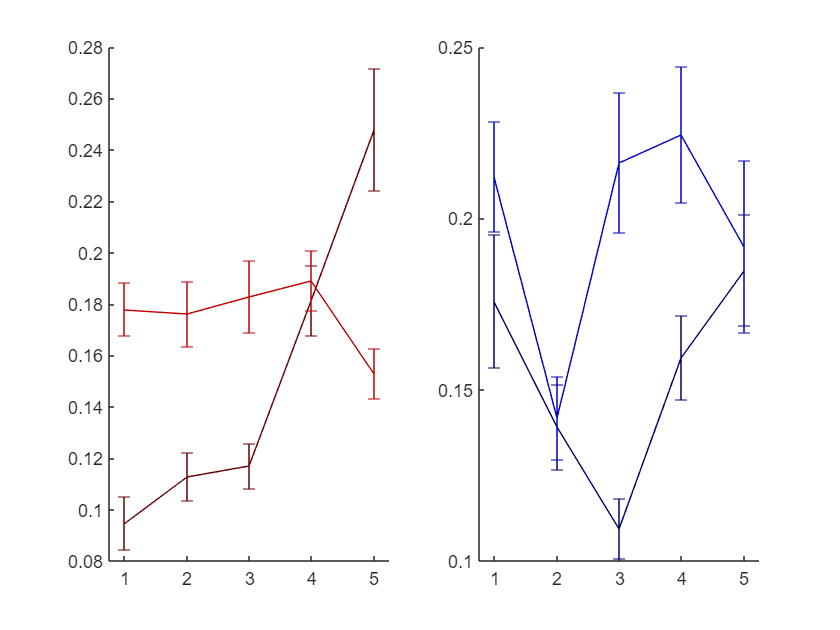

Current plot held
Current plot held


bm_mat = nan(26, i,2,2);
for n = 1:2
    if n == 1
        colorcodes = colorcodes_f;
        nlen = 26;
    else
        colorcodes = colorcodes_m;
        nlen = 22;
    end
    for i = 1:5
        bm_mat(1:nlen, i,1,n) = cag_mdI{i,n}(:,blocknum);
        bm_mat(1:nlen, i,2,n) = str_mdI{i,n}(:,blocknum);
    end
    subplot(1,2,n)
    hold
    me = errorbar(1:5, nanmean(bm_mat(:,:,1,n)), nanstd(bm_mat(:,:,1,n))/sqrt(length(find(~isnan(bm_mat(:,:,1,n))))), 'Color', colorcodes(2,:));
    errorbar(1:5, nanmean(bm_mat(:,:,2,n)), nanstd(bm_mat(:,:,2,n))/sqrt(length(find(~isnan(bm_mat(:,:,2,n))))), 'Color', colorcodes(1,:));
    
%    e{1,n} = errorbar(1:5, nanmean(auc_str(:,:,n)-auc_cag(:,:,n)), nanstd(auc_str(:,:,n)-auc_cag(:,:,n))/sqrt(length(find(~isnan(auc_cag(:,1,n))))), 'Color', colorcodes(1,:));
    
    set(get(me, 'Parent'), 'XLim', [0.75 5.25])

end